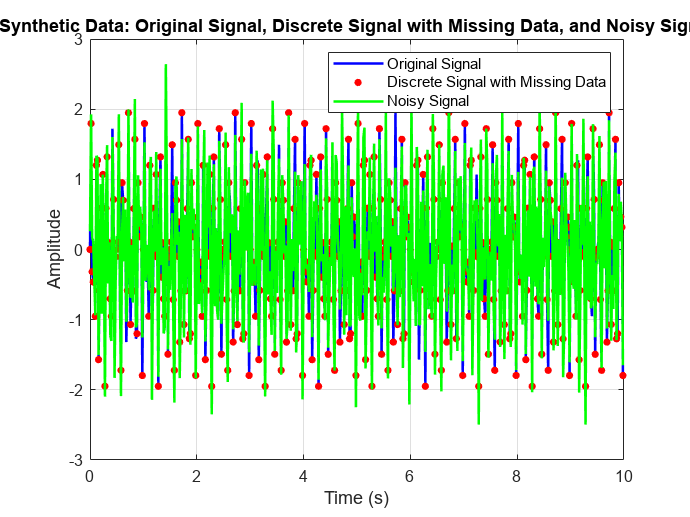

% Parameters
Fs = 50;                % Sampling frequency
N = 500;                % Number of observations
f1 = 10;                % Frequency of first sine wave (Hz)
f2 = 17;                % Frequency of second sine wave (Hz)
missing_percentage = 0.1;   % Percentage of missing data
SNR = 10;               % Signal-to-noise ratio

% Generate time vector
t = (0:N-1) / Fs;

% Generate continuous-time signal
signal = sin(2 * pi * f1 * t) + sin(2 * pi * f2 * t);

% Discretization (sampling)
discrete_signal = signal(1:N);

% Introduce missing data
missing_indices = randperm(N, floor(N * missing_percentage));
discrete_signal_missing = discrete_signal;
discrete_signal_missing(missing_indices) = NaN;

% Add noise to achieve desired SNR
% Calculate signal power
signal_power = mean(abs(discrete_signal).^2);
% Calculate noise power
noise_power = signal_power / SNR;
% Generate noise
noise = sqrt(noise_power) * randn(1, N);
% Add noise to signal
noisy_signal = discrete_signal + noise;

% Plotting
figure;
plot(t, signal, 'b', 'LineWidth', 1.5);
hold on;
plot(t, discrete_signal_missing, 'r.', 'MarkerSize', 15);
plot(t, noisy_signal, 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Synthetic Data: Original Signal, Discrete Signal with Missing Data, and Noisy Signal');
legend('Original Signal', 'Discrete Signal with Missing Data', 'Noisy Signal');
grid on;

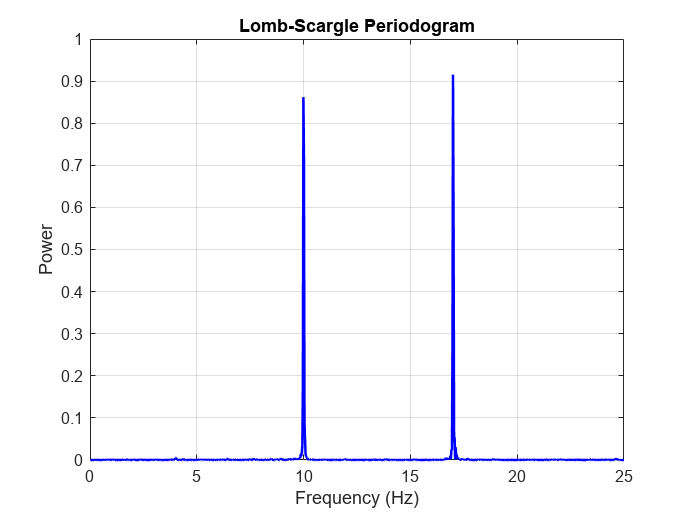


frequencies = linspace(0.01, 25, 1000);  % Frequencies to compute periodogram
y = noisy_signal;  % Assuming 'noisy_signal' is the observed data

% Parameters for gradient descent
max_iter = 1000;
learning_rate = 0.01;
lambda = .86; %L2 Regularization

% Compute Lomb-Scargle periodogram
[freq, power] = lomb_scale_periodogram(t, y, frequencies, max_iter, learning_rate, lambda);

% Plot Lomb-Scargle periodogram
figure;
plot(freq, power, 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Power');
title('Lomb-Scargle Periodogram');
grid on;

# We can see that the peaks are shown at frequencies of 10Hz and 17Hz.

function [freq, power] = lomb_scale_periodogram(t, y, frequencies, max_iter, learning_rate, lambda)
    % Mean-centering the signal
    y_mean = mean(y);
    y_centered = y - y_mean;
    
    % Number of observations
    N = length(t);
    
    % Initialize power array
    power = zeros(size(frequencies));
    
    % Loop through each frequency
    for i = 1:length(frequencies)
        omega = 2 * pi * frequencies(i);
        
        % Initialize parameters
        a = 1;
        b = 1;
        
        % Gradient descent
        for iter = 1:max_iter
            % Compute residuals
            residuals = y_centered - a * cos(omega * t) + b * sin(omega * t);
            
            % Compute gradients
            grad_a = -2 * sum(residuals .* cos(omega * t)) / N + 2 * lambda * a;
            grad_b = -2 * sum(residuals .* sin(omega * t)) / N + 2 * lambda * b;
            
            % Update parameters with L2 regularization
            a = a - learning_rate * grad_a;
            b = b - learning_rate * grad_b;
        end
        
        % Compute power at this frequency
        power(i) = (a^2 + b^2) / 2; %power for a signal with addition of two sine waves of frequencies a and b
    end
    
    % Return frequencies and corresponding power
    freq = frequencies;
end

